%rng('default')
dataFolder = 'E:\3. Mid Sweden Univ\BackupData\3rdYear2021\29.Paper5\ValmetDataset\Experiment21Sept27\Valmet_Ori_Gen_2class_MelSpec_Sept27\'; % Link to mel spectrogram images (both original sounds and synthesized sounds) of sounds

imds = imageDatastore(dataFolder, ...
    'IncludeSubfolders',true, ...
    'LabelSource', 'foldernames');

trainingNumFiles = 0.7;
[imdsTrain, imdsValidation] = splitEachLabel(imds, trainingNumFiles, 'randomize');

net = alexnet;

%net.Layers('input');
inputSize = net.Layers(1).InputSize;

## Replace final layers

if isa(net,'SeriesNetwork') 
  lgraph = layerGraph(net.Layers); 
else
  lgraph = layerGraph(net);
end

## Find the names of the two layers to replace

[learnableLayer,classLayer] = findLayersToReplace(lgraph);


numClasses = numel(categories(imdsTrain.Labels));

if isa(learnableLayer,'nnet.cnn.layer.FullyConnectedLayer')
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    
elseif isa(learnableLayer,'nnet.cnn.layer.Convolution2DLayer')
    newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
end

lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);

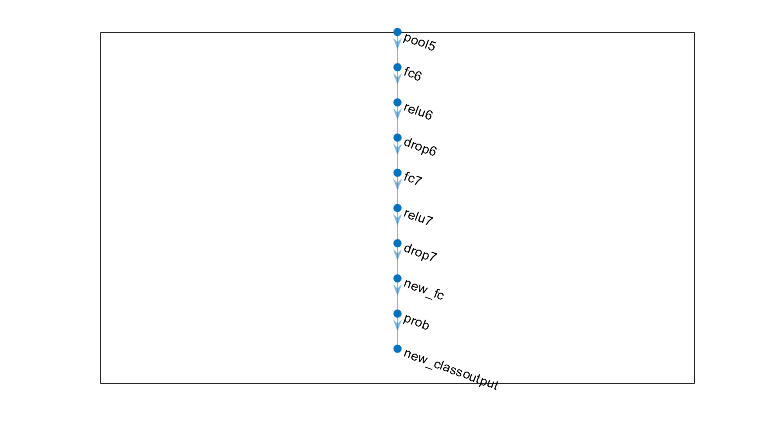

figure('Units','normalized','Position',[0.3 0.3 0.4 0.4]);
plot(lgraph)
ylim([0,10])

## Freeze Initial Layers

layers = lgraph.Layers;
connections = lgraph.Connections;

layers(1:10) = freezeWeights(layers(1:10));
lgraph = createLgraphUsingConnections(layers,connections);

## Train Network

pixelRange = [-30 30];
scaleRange = [0.9 1.1];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true);
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
    'DataAugmentation',imageAugmenter);

## To automatically resize the validation images without performing further data augmentation, use an augmented image datastore without specifying any additional preprocessing operations.

augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);

miniBatchSize = 10;
valFrequency = floor(numel(augimdsTrain.Files)/miniBatchSize);
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',50, ...
    'InitialLearnRate',3e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',valFrequency, ...
    'Verbose',false, ...
    'Plots','training-progress');

net = trainNetwork(augimdsTrain,lgraph,options);

save net;
%load('net.mat');


## Confusion matrix

[YPred,probs] = classify(net,augimdsValidation);
accuracy = mean(YPred == imdsValidation.Labels)

accuracy = 0.9412

## Confusion matrix

Create a confusion matrix chart from the true lprobsabels Y and the predicted labels predictedY.

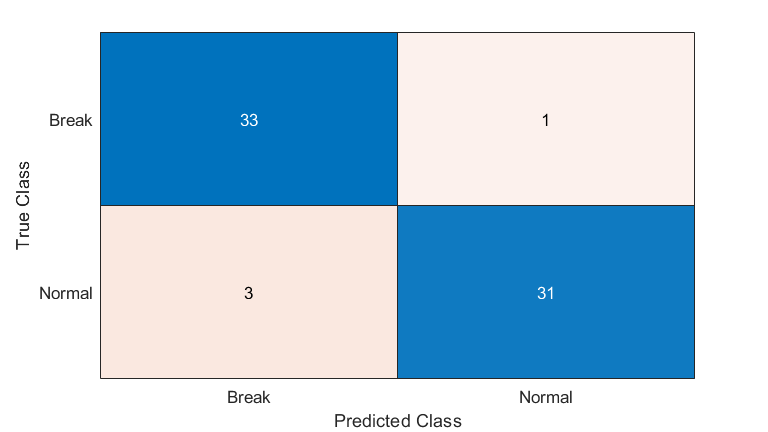

Y = imdsValidation.Labels;
cm = confusionchart(Y,YPred);

cm.NormalizedValues

ans =     33     1
     3    31


## Modify the appearance and behavior of the confusion matrix chart by changing property values. Add a title.

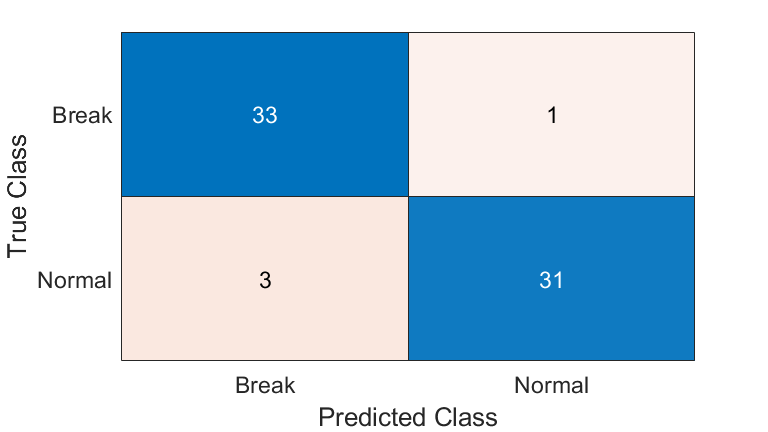

%cm.Title = 'Confusion matrix';

% Add column and row summaries.

%cm.RowSummary = 'row-normalized';
%cm.ColumnSummary = 'column-normalized';
%sortClasses(cm,'descending-diagonal')

%set(findobj(gca,'type','text'),'fontsize',100);
set(findall(gcf,'-property','FontSize'),'FontSize',14); % All font size

## Evalucation metrics for each class (precision, recall, sensitivity, ...)

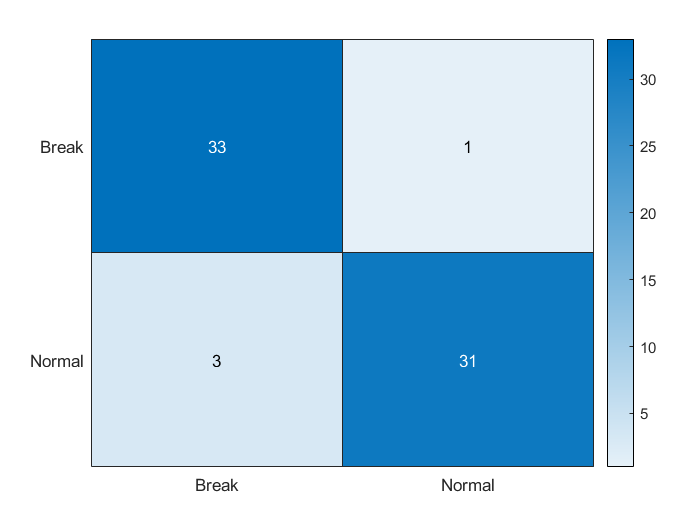

cms = confusionmatStats(Y,YPred);

%% Display confusion matrix
conf_mat_featsel = confusionmat(imdsValidation.Labels, YPred);
conf_mat_per_featsel = conf_mat_featsel*100./sum(conf_mat_featsel, 2);
labels = {'Break', 'Normal'};

% Visualize model performance
figure
heatmap(labels, labels, conf_mat_featsel);

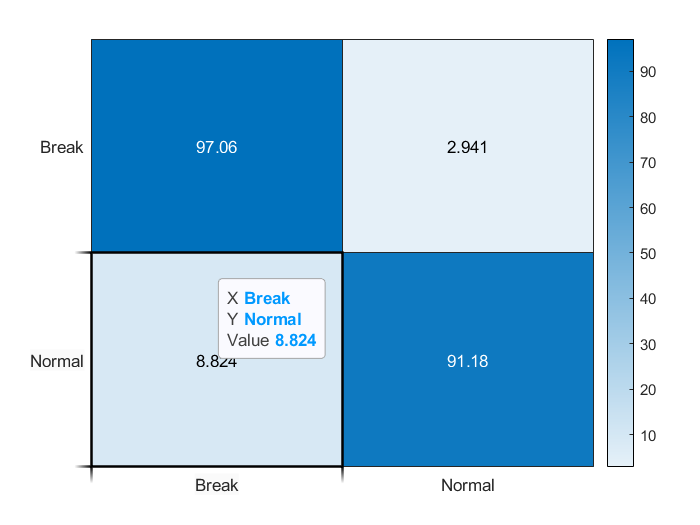


figure
heatmap(labels, labels, conf_mat_per_featsel);


h.Title = 'Test Confusion Matrix';